# Sample 12-5

## 画像復元

主-双対近接分離法 (PDS)

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Image restoration

Primal-dual splitting (PDS)

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

## 問題設定

(Problem settings)

    
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\lambda\|\mathbf{s}\|_1,\quad \mathrm{s.t.}\ \mathbf{Ds}\in[a,b]^2 $$


- 
$$\mathbf{D} = \left(\begin{array}{cc} \frac{2}{3} & \frac{1}{3}\end{array}\right)\colon\quad \mathbb{R}^2\rightarrow\mathbb{R}^1$$


- 
$$\mathbf{v}=\frac{1}{2}\in\mathbb{R}^1$$


- 
$$\lambda\in[0,\infty)$$


- 
$$\mathbf{s}\in\mathbb{R}^2$$


- 
$$a,b\in\mathbb{R}$$


D = [2 1]/3;
v = 0.5;
a =  -0.5;
b =   0.0;

### 関数プロット

(Function plot)

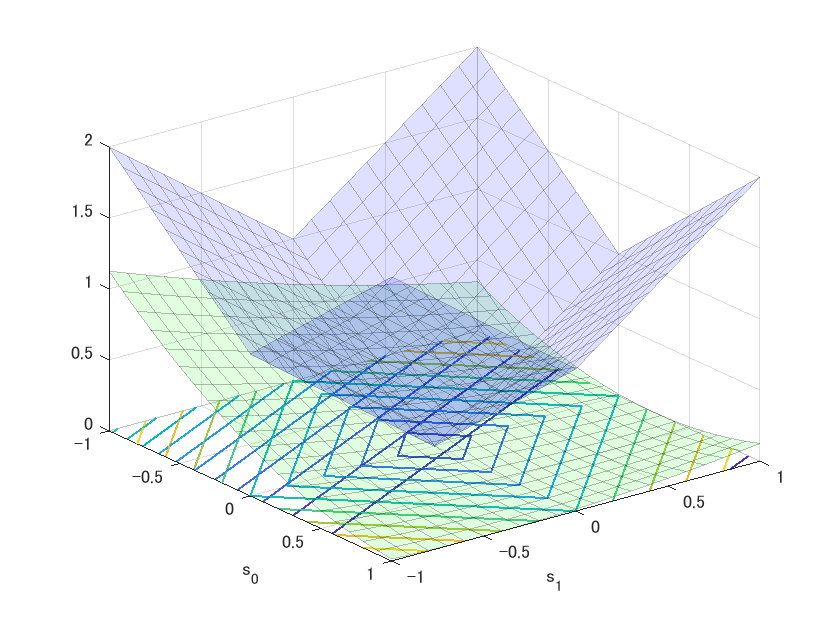

% Function settings
f = @(s0,s1) 0.5*(v-(D(1)*s0+D(2)*s1)).^2;
g = @(s0,s1) (abs(s0)+abs(s1));
% Variable settins
s0 = linspace(-1,1,21);
s1 = linspace(-1,1,21);
[S0,S1] = ndgrid(s0,s1);
F = f(S0,S1);
G = g(S0,S1);
% Surfc plot of the fidelity
figure(1)
hf = surfc(s0,s1,F);
hf(1).FaceAlpha = 0.125;
hf(1).FaceColor = 'green';
hf(1).EdgeAlpha = 0.25;
hf(2).LineWidth = 1;
set(gca,'YDir','reverse');
hold on
% Surfc plot of the regularizer
hg = surfc(s0,s1,G);
hg(1).FaceAlpha = 0.125;
hg(1).FaceColor = 'blue';
hg(1).EdgeAlpha = 0.25;
hg(2).LineWidth = 1;
xlabel('s_1')
ylabel('s_0')
hold off

### パラメータ設定

(Parameter settings)

lambda = 0.2;
gamma1 = 0.4;
niters = 20;

## 制約付き$\ell_1$ -ノルム正則化最小自乗法による近似

($\ell_1$ -norm-regularized least square method with constraint)

         
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\lambda\|\mathbf{s}\|_1,\quad \mathbf{Ds}\in[a,b]^2$$


主-双対近接分離法に帰着させる．(Reduced to a primal-dual splitting method)

         
$$\hat{\mathbf{x}}=\arg\min_{\mathbf{x} \in V} f(\mathbf{x})+g(\mathbf{x})+h(\mathbf{Lx})$$


- 
$$\mathbf{L}\in\mathbb{R}^{K\times L}$$


- $f(\cdot),g(\cdot)\in\Gamma_0(\mathbb{R}^L)$, $h(\cdot)\in\Gamma_0(\mathbb{R}^K)$: Convex functions

- $f(\cdot)$ is differentiable ( $\beta$-Lipschitz continuous)

- $\Gamma_0(\mathbb{R}^L)$ : Set of proper semi-lower-continuous convex functions

【Example】

- 
$$f(\mathbf{s})=\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2$$


- 
$$g(\mathbf{s})=\lambda\|\mathbf{s}\|_1$$


- 
$$h(\mathbf{Ls})=\imath_{[a,b]^2}(\mathbf{Ds})$$


関数プロット (Function plot)

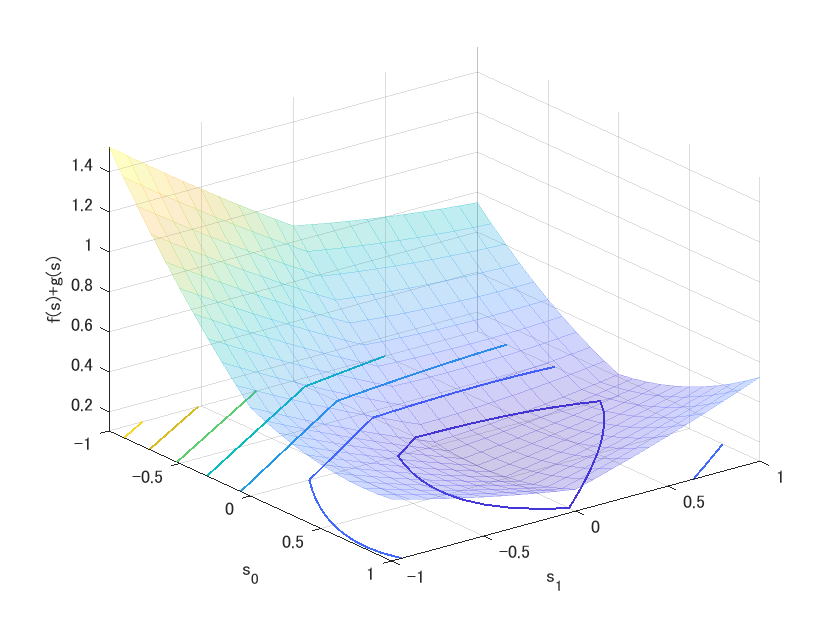

% Function setting
fg = @(s0,s1) 0.5*(v-(D(1)*s0+D(2)*s1)).^2 + lambda*(abs(s0)+abs(s1));
% Surfc plot of cost function f+g
figure(2)
J = fg(S0,S1);
hf = surfc(s0,s1,J);
hf(1).FaceAlpha = 0.25;
hf(1).EdgeAlpha = 0.25;
hf(1).EdgeColor = 'interp';
hf(2).LineWidth = 1;
set(gca,'YDir','reverse')
ylabel('s_0')
xlabel('s_1')
zlabel('f(s)+g(s)')
hold on

### 主-双対近接分離法

(Primal-dual splitting method)

- Initialization: $\mathbf{x}^{(0)}$, $t\leftarrow 0$

- Primal: $\mathbf{x}^{(t+1)} \leftarrow \mathrm{prox}_{\gamma_{1} g}\left(\mathbf{x}^{(t)}-\gamma_{1}\left(\nabla_{x} f\left(\mathbf{x}^{(t)}\right)+\mathbf{L}^{T} \mathbf{y}^{(t)}\right)\right) $

- Dual: $\mathbf{y}^{(t+1)}\leftarrow \mathrm{prox}_{\gamma_2h^\ast}\left(\mathbf{y}^{(t)}+\gamma_2\mathbf{L}(2\mathbf{x}^{(t+1)}-\mathbf{x}^{(t)})\right)$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

【Example】

- 
$$\nabla_\mathbf{x}f(\mathbf{x})=\mathbf{D}^T(\mathbf{Dx}-\mathbf{v})$$


- 
$$\mathrm{prox}_{\gamma\lambda\|\cdot\|_{1}}(\mathbf{x})=\mathcal{T}_{\gamma\lambda}(\mathbf{x})=\mathrm{sign}(\mathbf{x})\odot\max(\mathrm{abs}(\mathbf{x})-\gamma\lambda\mathbf{1},\mathbf{0})$$


- 
$$\mathrm{prox}_{\gamma\imath_{C}^\ast}(\mathbf{y})=\mathbf{y}-\gamma\mathcal{P}_C(\gamma^{-1}\mathbf{y})$$


ただし，(where) $C=[a,b]^N$

        
$$\mathcal{P}_{[a, b]^{N}}(\mathbf{x})=\min \{\max \{\mathbf{x}, a\}, b\}$$


ソフト閾値処理 (Soft-thresholding)

softthresh = @(x,t) sign(x).*max(abs(x)-t,0);

初期化 (Initialization)

sp = 2*rand(2,1)-1; % in [-1,1]^2

ステップサイズ $\gamma_2$ の設定 (Settings for stepsize $\gamma_2$)

beta = D*D';
tau2 = D*D';
gamma2 = 1/(1.05*tau2)*(1/gamma1-beta/2);
assert((1/gamma1 - gamma2*tau2) > beta/2,'Step size condition is violated.')

主双対近接分離法 (Prima-dual splitting method)

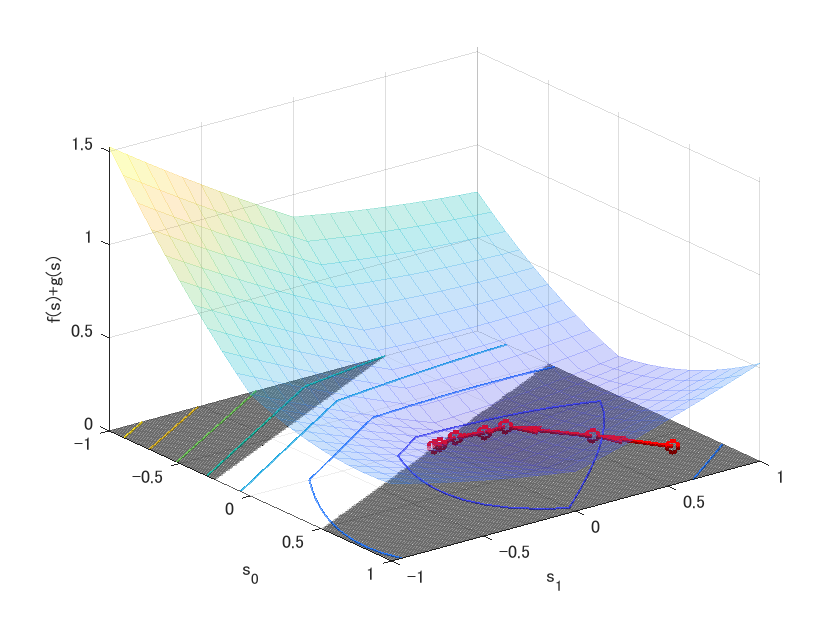

sf0 = -1:.01:1;
sf1 = -1:.01:1;
[Sf0,Sf1] = ndgrid(sf0,sf1);
ic = @(x1,x2) (D(1)*x1+D(2)*x2)>=a & (D(1)*x1+D(2)*x2)<=b;
C = repmat(ic(Sf0,Sf1),[1 1 3]);
hc = surf(sf0,sf1,zeros(size(C,1),size(C,2)),double(C));
hc.EdgeColor = 'interp';
hc.EdgeAlpha = 0.25;
hc.FaceAlpha = 0.25;
y = D*sp;
for idx=0:niters-1
    % Preious state
    s(1,1) = sp(1); % s0
    s(2,1) = sp(2); % s1
    % Primal
    sg = sp-gamma1*D'*((D*sp-v)+y);
    sc = softthresh(sg,gamma1*lambda);
    % Dual
    u = y + gamma2*D*(2*sc-sp);
    y = u - gamma2*min(max(u/gamma2,a),b);
    % Current state
    s(1,2) = sc(1); % s0
    s(2,2) = sc(2); % s1
    % Quiver plot
    xp = s(2,1);
    yp = s(1,1);
    xn = s(2,2);
    yn = s(1,2);
    hp = quiver(xp,yp,xn-xp,yn-yp);
    hp.Marker = 'o';
    hp.ShowArrowHead = 'on';
    hp.MaxHeadSize = 120;
    hp.MarkerSize = 6;
    hp.MarkerEdgeColor = 'r';
    hp.Color = 'r';
    hp.LineWidth = 2;
    % Update
    sp = sc;
end
hold off

### パラメータ設定

(Parameter settings)

- sgm: ノイズ標準偏差 $\sigma_w$ (Standard deviation of noise)

% Parameter settings
lambda = 10^-2.4

lambda = 0.0040

gamma1 = 10^-2.4

gamma1 = 0.0040

sgmuint8 = 10; 
sgm = sgmuint8/255;
niters = 80;

## 画像の読込

(Read image)

u = rgb2gray(im2double(imread('./data/kodim23.png')));

## 観測画像

(Observation image)

- 
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


% Definition of measurment process
psf = fspecial('motion',21,11);
measureproc = @(x) imfilter(x,psf,'conv','circular');
% Adjoint process of the measurment process
measureadjp = @(x) imfilter(x,psf,'corr','circular');
% Simulation of AWGN
v = imnoise(measureproc(u),'gaussian',0,sgm^2);

### 全変動正則化

(Total-variation regularization)

PDSの応用例として全変動正則化による画像復元を行う．(As an application of PDS, total variation regularization is applied to image restoration.)

#### 問題設定 (Problem settings)

        
$$\widehat{\mathbf{u}}=\arg \min _{\mathbf{u} \in[0,1]^{N}} \frac{1}{2}\|\mathbf{v}-\mathbf{P} \mathbf{u}\|_{2}^{2}+\lambda\|\mathbf{u}\|_{\mathrm{TV}}$$


            
$$\Downarrow$$


        
$$\widehat{\mathbf{u}}=\arg \min _{u \in \mathbb{R}^{N}} \frac{1}{2 \lambda}\|\mathbf{v}-\mathbf{Pu}\|_{2}^{2}+\imath_{[0,1]^{N}}(\mathbf{u})+\|\nabla \mathbf{u}\|_{1,2}$$


#### アルゴリズム (Algorithm)

- Initialization: $\mathbf{u}^{(0)}, \mathbf{y}^{(0)}, t \leftarrow 0$

- 
$$\mathbf{u}^{(t+1)} \leftarrow \mathcal{P}_{[0,1]^{N}}\left(\mathbf{u}^{(t)}-\gamma_{1}\left(\lambda^{-1} \mathbf{P}^{T}(\mathbf{P} \mathbf{u}^{(t)}-\mathbf{v})+\mathbf{\nabla}^{T} \mathbf{y}^{(t)}\right)\right)$$


- 
$$\mathbf{y}^{(t+1)} \leftarrow \mathrm{prox}_{\gamma_{2}\left(\|\cdot\|_{1,2}\right)^{*}}\left(\mathbf{y}^{(t)}+\gamma_{2} \mathbf{\nabla}\left(2 \mathbf{u}^{(t+1)}-\mathbf{u}^{(t)}\right)\right)$$


- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

ただし，(where)

- 
$$\mathrm{prox}_{\gamma\|\cdot\|_{1,2}^{*}}(\mathbf{x})=\mathbf{x}-\gamma \mathrm{prox}_{\gamma^{-1}\|\cdot\|_{1,2}}\left(\gamma^{-1} \mathbf{x}\right)$$


- $\left[\gamma \mathrm{prox}_{\gamma^{-1}\|\cdot\|_{1,2}}\left(\gamma^{-1} \mathbf{x}\right)\right]_{\mathcal{I}_{n}}=\mathbf{x}_{\mathcal{I}_{n}} \odot \max \left\{\mathbf{1}-\frac{1}{\left\|\mathbf{x}_{\mathcal{I}_{n}}\right\|_{2}} \mathbf{1}, 0\right\}$ (Soft-thresholding for magnitude of $\nabla\mathbf{x}$)

- 
$$\gamma_{1}^{-1}-\gamma_{2}\left(\sigma_{\max }(\nabla)\right)^{2} \geq(2 \lambda)^{-1}\left(\sigma_{\max }(\mathbf{P})\right)^{2}$$


勾配フィルタ (Gradient filter)

g0 = [   0     1     0
         0    -1     0
         0     0     0 ]; % Vetical difference
g1 = rot90(g0);  % Horizontal difference
gradproc = @(x) cat(3,imfilter(x,g0,'conv','circ'),imfilter(x,g1,'conv','circ'));
gradadjp = @(x) imfilter(x(:,:,1),g0,'corr','circ') + imfilter(x(:,:,2),g1,'corr','circ');

初期化 (Initialization)

up = v;
yp = gradproc(v);

ステップサイズ $\gamma_2$ の設定 (Settings for stepsize $\gamma_2$)

nPoints = 2.^nextpow2(size(v));
beta = max(abs(fftn(psf,nPoints)).^2,[],'all')/lambda; % (σmax(P))^2/λ
tau2 = max(abs(fftn(g0,nPoints)).^2,[],'all');  % (σmax(G))^2
gamma2 = 1/(1.05*tau2)*(1/gamma1-beta/2);
assert((1/gamma1 - gamma2*tau2) > beta/2,...
    ['Step size condition is violated. γ1 must be less than ' num2str(2/beta)])

主-双対近接分離法 (Primal-dual splitting method)

for idx=0:niters-1
    % Primal step
    ug = measureadjp(measureproc(up)-v);
    uc = min(max(up-gamma1*(ug/lambda + gradadjp(yp)),0),1);
    % Dual step
    yt = yp + gamma2*gradproc(2*uc - up);
    yc = yt - magshrink(yt); % MAGSHRINK is defined at the end of this script
    % Update
    up = uc;
    yp = yc;
end

### 復元画像

(Restored image)

r = uc;

### 画像表示

(Image show)

figure(1)
imshow(u);

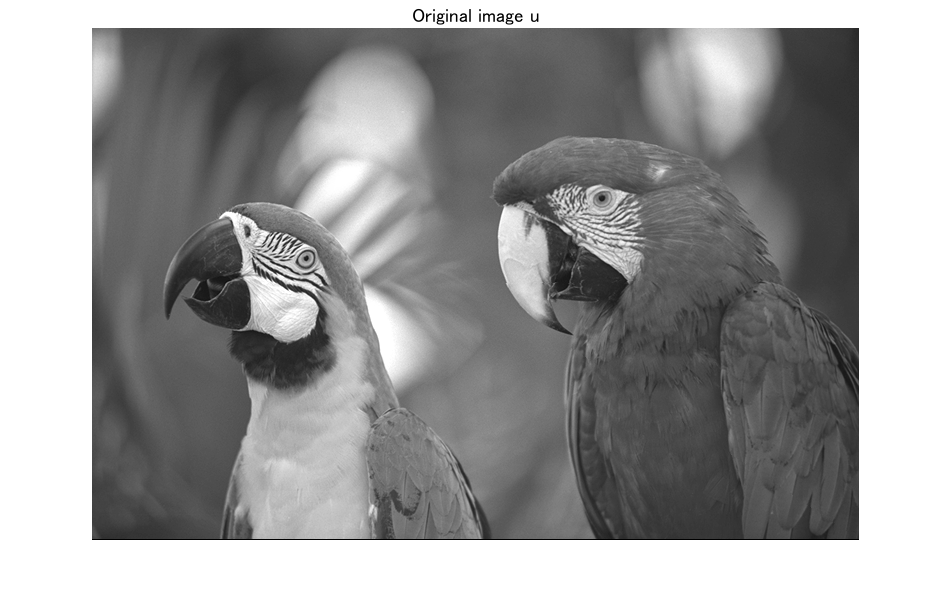

title('Original image u')

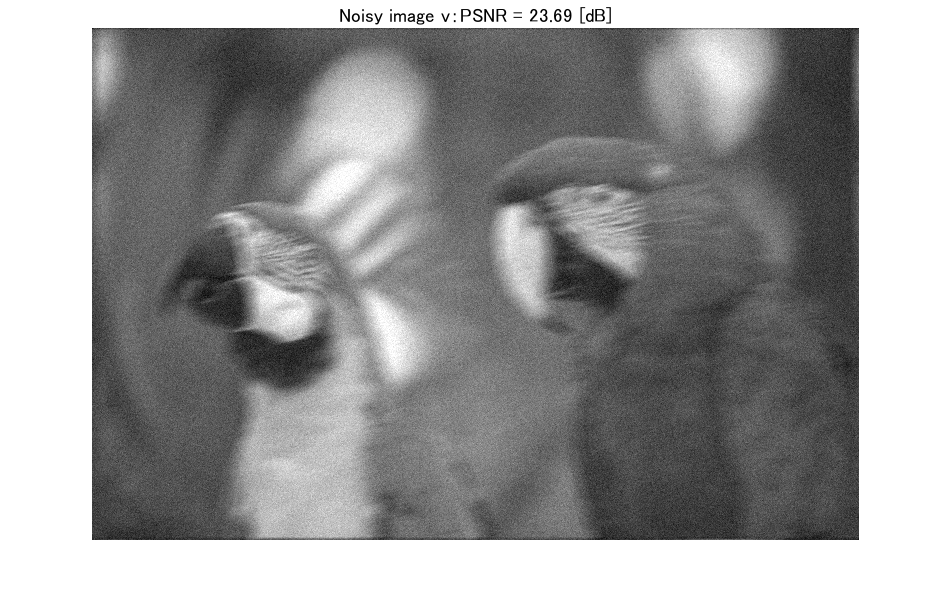

figure(2)
imshow(v)
title(sprintf('Noisy image v：PSNR = %5.2f [dB]',psnr(u,v)))

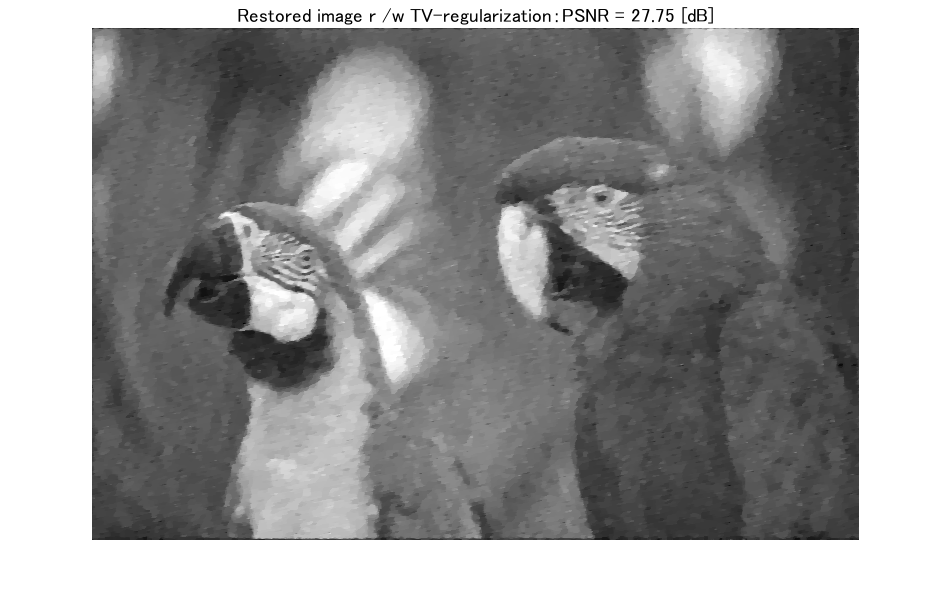

figure(3)
imshow(r)
title(sprintf('Restored image r /w TV-regularization：PSNR = %5.2f [dB]',psnr(u,r)))

### 振幅ソフト閾値関数

(Magnitude soft-thresholding)

function y = magshrink(x)
    Gy = x(:,:,1);
    Gx = x(:,:,2);
    Gmag = imgradient(Gx,Gy);
    map = max(1 - 1./Gmag,0);
    y = x.*map;    
end

© Copyright, Shogo MURAMATSU, All rights reserved.